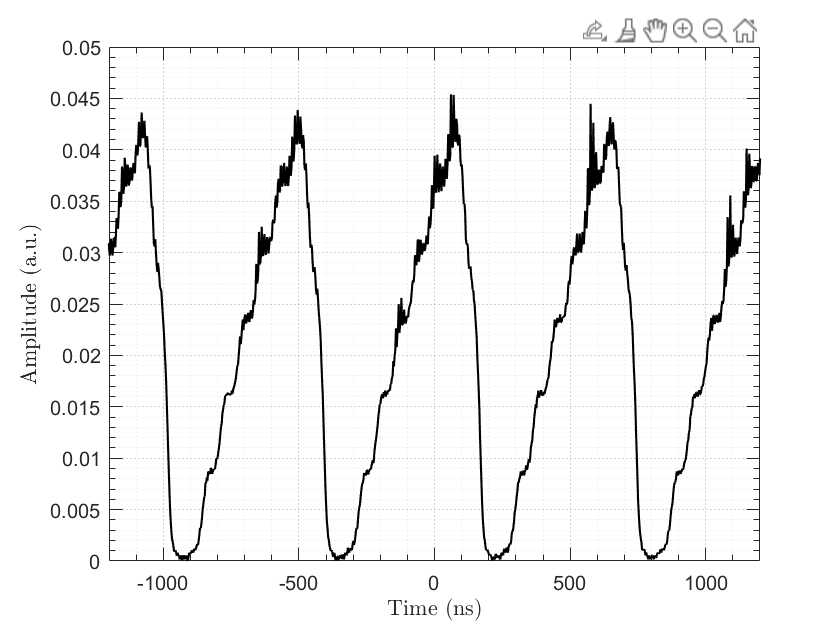

cd 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data';

% Read the data from the CSV file
data = readmatrix('C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\scope_70mASop2.csv');

% Extract wavelength and power column6
time = data(:, 1)*1e9;
voltage = data(:, 2)*1e3;
voltage = rescale(voltage,0,1);

plot(time,voltage, "Color", [0 0 0], "LineWidth", 1.05)
xlabel('Time (ns)', "Interpreter","latex");
ylabel('Amplitude (a.u.)',"Interpreter","latex");
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

xlim([-1200 1200])

DataOrigin = table(time, voltage);
writetable(DataOrigin, 'processed_trace3.csv');


% Get two points from mouse click
[x, y] = ginput(4);


% Calculate distance between the points
dx1 = x(2) - x(1);
dy1 = y(2) - y(1);
distance1 = sqrt(dx1^2 + dy1^2);

dx2 = x(4) - x(3);
dy2 = y(4) - y(3);
distance2 = sqrt(dx2^2 + dy2^2);

% Display results
fprintf('Point 1: (%.3f, %.3f)\n', x(1), y(1));

Point 1: (-1080.184, 0.042)


fprintf('Point 2: (%.3f, %.3f)\n', x(2), y(2));

Point 2: (-501.382, 0.042)


fprintf('Point 1: (%.3f, %.3f)\n', x(3), y(3));

Point 1: (-711.521, 0.023)


fprintf('Point 2: (%.3f, %.3f)\n', x(4), y(4));

Point 2: (-423.963, 0.023)


fprintf('Δx = %.3f, Δy = %.3f, Peak to peak distance = %.3f\n ns', dx1, dy1, distance1);

Δx = 578.802, Δy = -0.001, Peak to peak distance = 578.802
 ns

fprintf('Δx = %.3f, Δy = %.3f, Pulse width = %.3f\n ns', dx2, dy2, distance2);

Δx = 287.558, Δy = 0.000, Pulse width = 287.558
 ns